# Dynamometer Simulation - Sina Atalay

Simulation of an electric dynamometer with a PID controller.

clc
clear
close

## Specifications of the system

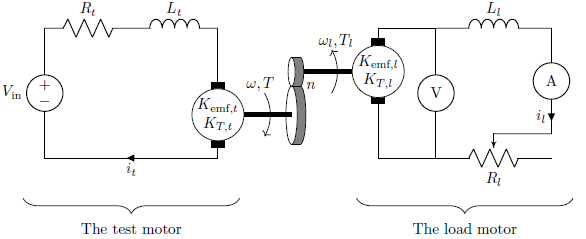

**The test motor:**

V_t=12;                             % [V]
K_T_t=2/44;                         % [N*m/A]
K_emf_t=2/44/0.993287399771488;     % [V*s]
R_t=V_t*K_T_t/2.3;                  % [ohm]
L_t=1.5*10^-3;                      % [H]

TestMotor=[V_t, K_T_t, K_emf_t, R_t, L_t];

**Connection:**

n=50;
I=0.025;      % [kg*m^2]
c=0.001;       % [N*s]

Connection=[n, I, c];

**The load motor:**

K_emf_l=0.02;       % [V*s]
K_T_l=0.02;         % [N*m/A]
R_l_minimum=5;      % [ohm]
L_l=L_t;            % [H]

LoadMotor=[K_emf_l, K_T_l, R_l_minimum, L_l];

## PID Control

close
DesiredLoad=0.752;
% When the controlling starts:
StartControl= 10;   % [s]

**Tuning:**

Kp=1000;
Kd=0;
Ki=1000;
PIDTune=[Kp Kd Ki];

**Simulation:**

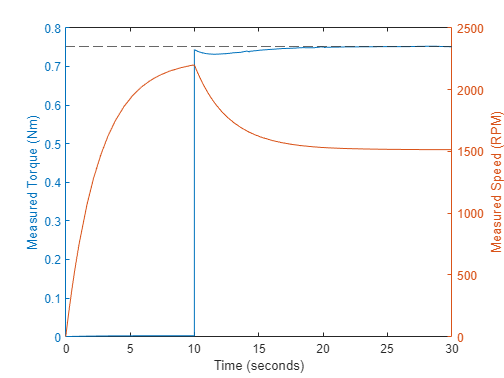

C=[0,   0,          n*K_T_l;
   0,   60/(2*pi),  0];
D=[0;0];

[t,x] = ode15s(@(t,x) xDot(t, x, DesiredLoad, StartControl, PIDTune, TestMotor, Connection, LoadMotor), [0,30], [0,0,0]);
y=C*x';

% Plot the results:
yyaxis left
plot(t,y(1,:));
hold on;
ylabel("Measured Torque (Nm)");
xlabel("Time (seconds)");
yline(DesiredLoad, "--");
yyaxis right
plot(t,y(2,:));
hold off;
ylabel("Measured Speed (RPM)");

## Functions

function result=xDot(t, x, DesiredLoad, StartControl, PIDTune, TestMotor, Connection, LoadMotor)
    % Returns the derivaties of the states.
    V_t=TestMotor(1);
    K_T_t=TestMotor(2);
    K_emf_t=TestMotor(3);
    R_t=TestMotor(4);
    L_t=TestMotor(5);
    
    n=Connection(1);
    I=Connection(2);
    c=Connection(3);

    K_emf_l=LoadMotor(1);
    K_T_l=LoadMotor(2);
    R_l_min=LoadMotor(3);
    L_l=LoadMotor(4);
    
    if(t>StartControl)
        R_l=Calculate_R_l(t, x, DesiredLoad, PIDTune, K_T_l, n, R_l_min);
    else
        R_l=99999;
    end

    A=[-R_t/L_t,    -K_emf_t/L_t,   0;
       K_T_t/I,     -c/I,           -n*K_T_l/I;
       0,           n*K_emf_l/L_l,  -R_l/L_l];
    B=[V_t/L_t; 0; 0];
    
    result=A*x+B;
end

function R_l=Calculate_R_l(t, x, DesiredLoad, PIDTune, K_T_l, n, R_l_min)
    %Returns the R_l value, calculated with PID.
    persistent t_prev i_l_prev Integral;
    if isempty(t_prev)
       Integral=0;
       t_prev=t;
       i_l_prev=x(3);
    end
    
    Kp=PIDTune(1);
    Kd=PIDTune(2);
    Ki=PIDTune(3);

    if(-DesiredLoad + n*x(3)*K_T_l>0)
        a=5;
    end

    % PROPORTIONAL:
    P=-(DesiredLoad - n*x(3)*K_T_l);
    R_l=Kp*P;
   
    % INTEGRAL:
    Integral=Integral-(DesiredLoad - n*x(3)*K_T_l)*(t-t_prev);
    R_l=R_l+Ki*Integral;

    % DERIVATIVE:
    if(t~=t_prev)
        D=(n*x(3)*K_T_l-n*i_l_prev*K_T_l)/(t-t_prev);
        R_l=R_l+Kd*D;
    end

    if(R_l<R_l_min)
        R_l=R_l_min;
    end

    i_l_prev=x(3);
    t_prev=t;
end